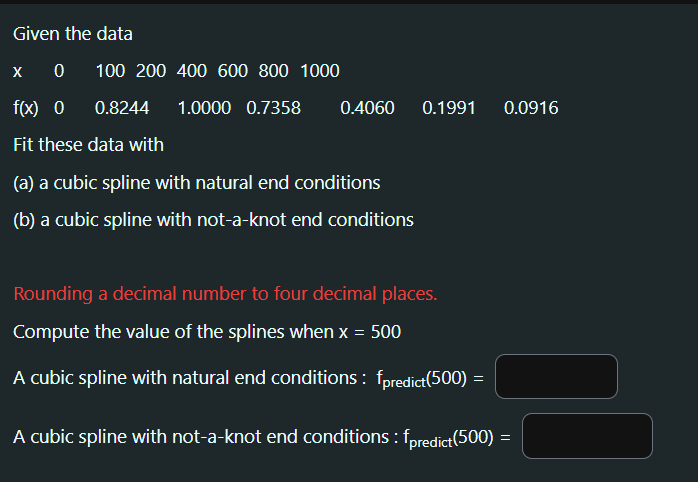

Data 

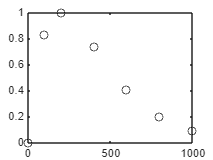

x = [0 100 200 400 600 800 1000];
y = [0 	0.8244 	1.0000   0.7358	0.4060	0.1991	0.0916];

plot(x,y,'ko')
hold on

A cubic spline with natural end conditions

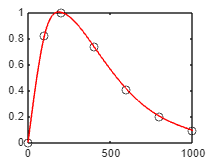

% Given data points
x = [0 100 200 400 600 800 1000];
y = [0 	0.8244 	1.0000   0.7358	0.4060	0.1991	0.0916];

% Define the points at which you want to interpolate
xx = 0 : 1 : 1000;

% Generate the interpolated values using cubic spline with natural end conditions
pp = csape(x, y, 'variational'); % 'variational' option enforces natural end conditions
yy = ppval(pp, xx); % Evaluate the spline at specified points

% Plot the original data points
figure
plot(x, y, 'ko')
hold on

% Plot the interpolated spline
plot(xx, yy, 'r-')
hold off


x_test = 500;
y_pred = ppval(pp,x_test)

y_pred = 0.5603

A cubic spline with not-a-knot end conditions

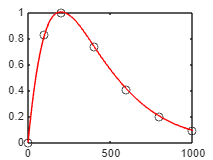

% Generate the interpolated values using cubic spline with natural end conditions
pp = csape(x, y, 'not-a-knot'); % 'variational' option enforces natural end conditions
yy = ppval(pp, xx); % Evaluate the spline at specified points

% Plot the original data points
figure
plot(x, y, 'ko')
hold on

% Plot the interpolated spline
plot(xx, yy, 'r-')
hold off


x_test = 500;
y_pred = ppval(pp,x_test)

y_pred = 0.5576